% Luria Delbruck Experiment 
clc
clear all


%Initialize the setup
iter = 10000; %iterations of experiments
n_gen = 13; %number of generations
p_mut = 0.005; %probability of mutation
pop = 1;

global var1;
global var2;

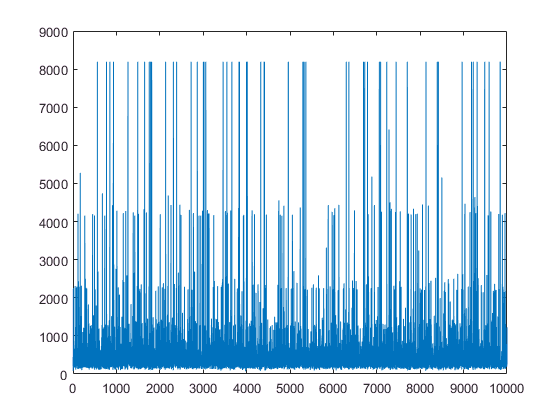


%Cell Division

mut_array = zeros(iter,2);

for i = 1:iter
    
    generation(n_gen,pop,0,p_mut);
    
    mut_array(i,1) = i;
    mut_array(i,2) = var2;
    
end
plot(mut_array(:,1),mut_array(:,2))


avg = mean(mut_array(:,2))

avg = 508.7588

stda  = std(mut_array(:,2))

stda = 767.1550

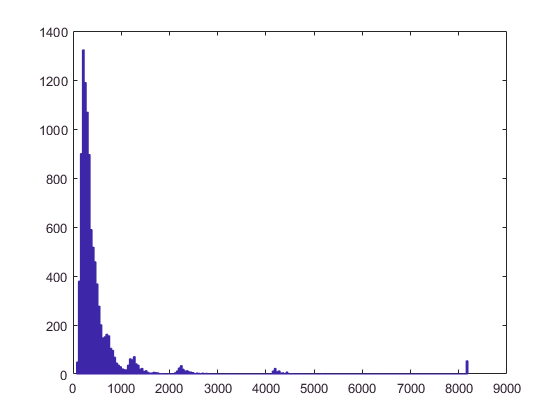


hist(mut_array(:,2),200)

function  [res_pop, res_mut]= generation(n_gen,cur_pop, cur_mut, p_mut)
    
    global var1;
    global var2;
    var1 = 0;
    var2 = 0;
    
    
    nut = cur_pop-cur_mut;
    new_mut = 0;
    for j = 1:nut
        r = rand();
  
        if r < p_mut
            ismut = 1;            
            new_mut = new_mut + 1;
        end
    end
    cur_mut;
    res_pop = 2*cur_pop;
    res_mut = 2*(cur_mut+new_mut);
    
    var1 = var1+res_pop;
    var2 = var2+res_mut;
    
    if res_pop == 2^n_gen
        return
    end
    
    generation(n_gen,res_pop,res_mut,p_mut);
end